## Main function

Prepare Data and Input 

% Read data symbols and category range

filename = "IDX Stock Symbol Category Market Cap.xlsx";
sheetname = "Latest symbols";
symdbase = readtable (filename,"Sheet", sheetname) ;
A = readtable (filename, "Sheet", "Cap Category Range") ;
capCategRange = sortrows(A,"LB","ascend") ;
clearvars A

% Categorize symbols based on market cap
binEdge = sort (vertcat (capCategRange.LB, 10^6),1,"ascend") ;
CapCategory = discretize (symdbase.MarketCap_InRpTn, binEdge, capCategRange.CapCategory) ;
CapCategory = table (CapCategory) ;
symdbaseT = [symdbase, CapCategory] ;
clearvars symdbase 

% Fetch data from yahoo finance
symList = string(symdbaseT.Symbol);
startdate = '1-Jan-2018';
enddate = datetime ('today');

tStart = tic ;
priceVolumeRaw = getDataYahooIDXPVFcn (symList, startdate, enddate)
tStop = toc(tStart)

% Save priceVolumeRaw
save ("WFATradeData.mat", "priceVolumeRaw");


%% Clean data
tStart = tic ;

% load priceVolumeRaw
load ("WFATradeData.mat", "priceVolumeRaw")
priceVolumeClean = dataCleaningFcn (priceVolumeRaw)
tStop = toc(tStart) 

% Save to matfile for easy access
save ("WFATradeData.mat", "priceVolumeRaw", "priceVolumeClean");


Optimize parameters for WFA

% WFA Preparation and Parameters Settings
load("WFATradeData.mat", "priceVolumeClean")

paramSetUp

walk_i = 1

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    272    52     1     7    10    15   104    23    15     4     6


fval = -7.0155

exitflag = 0

outpt = struct with fields:
        elapsedtime: 136.1517
          funccount: 200
    constrviolation: 0
               ineq: [-0.1055 -4.0107 0 -0.1900 -0.3117]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    163    79     1     9     4    15    96    27    20     1     5


fval = -21.2276

exitflag = 0

outpt = struct with fields:
        elapsedtime: 135.4626
          funccount: 200
    constrviolation: 0
               ineq: [-0.0211 -3.9181 0 -0.1749 -0.3135]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    105    63     1     1     4    15    61    10     5     4     7


fval = -906.2798

exitflag = 0

outpt = struct with fields:
        elapsedtime: 134.1635
          funccount: 200
    constrviolation: 0
               ineq: [-0.0241 -7.3739 0 -0.0946 -0.2446]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    149    25    11     7     4     4   104     1    19     2     5


fval = -3.6874

exitflag = 0

outpt = struct with fields:
        elapsedtime: 126.6119
          funccount: 200
    constrviolation: 0
               ineq: [-0.0828 -3.4058 0 -0.2000 -0.3048]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    275    86     1     1     3    10    92     9    18     3     8


fval = -34.5890

exitflag = 0

outpt = struct with fields:
        elapsedtime: 123.7185
          funccount: 200
    constrviolation: 0
               ineq: [-0.0781 -5.7817 0 -0.2000 -0.2946]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    197    75     1     7     7    15   117     7    16     6     5


fval = -1.6011

exitflag = 0

outpt = struct with fields:
        elapsedtime: 139.6976
          funccount: 200
    constrviolation: 0
               ineq: [-0.0867 -0.9819 0 -0.1444 -0.3143]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


walk_i = 2

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    285    18     1     7     9     8   106    30     9     6     5


fval = -11.6001

exitflag = 0

outpt = struct with fields:
        elapsedtime: 119.4017
          funccount: 200
    constrviolation: 0
               ineq: [-0.1038 -4.8646 0 -0.2000 -0.3143]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    298    56     1     5     9    15    97    23    16     3     5


fval = -11.2487

exitflag = 0

outpt = struct with fields:
        elapsedtime: 128.5876
          funccount: 200
    constrviolation: 0
               ineq: [-0.0142 -3.6237 0 -0.2000 -0.2651]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    213    48     1     1     9    15    67    25    15     3     2


fval = -934.3165

exitflag = 0

outpt = struct with fields:
        elapsedtime: 117.2943
          funccount: 200
    constrviolation: 0
               ineq: [-0.0220 -7.5481 0 -0.0784 -0.2466]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =     65    19     1     4     7     1   111    14     8     1     5


fval = -4.5882

exitflag = 0

outpt = struct with fields:
        elapsedtime: 135.1906
          funccount: 200
    constrviolation: 0
               ineq: [-0.0809 -3.9062 0 -0.2000 -0.3105]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =     64    56     1     3     4    12   110     3    16     2     8


fval = -37.5998

exitflag = 0

outpt = struct with fields:
        elapsedtime: 100.9550
          funccount: 200
    constrviolation: 0
               ineq: [-0.0128 -5.8435 0 -0.1955 -0.2351]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


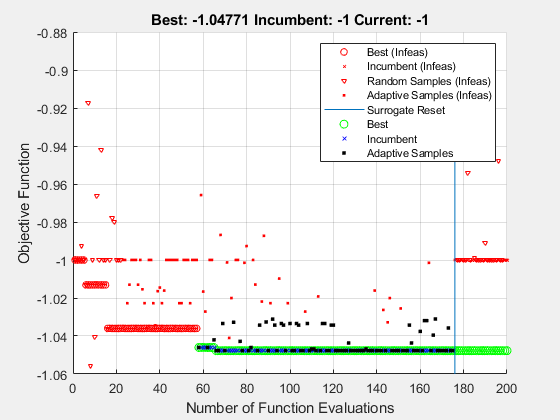

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    284   123    27     8     3    12   119    10    14     2     2


fval = -1.0477

exitflag = 0

outpt = struct with fields:
        elapsedtime: 124.8935
          funccount: 200
    constrviolation: 0
               ineq: [-0.1423 -0.2302 0 -0.1928 -0.3428]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


% Optimize parameter for each walk
tStart = tic ;
optimParamsScript ;

tStop = toc(tStart)

tStop = 1.5248e+03

% Save Opimtized parameters for WFA
save ("WFATradeData.mat", "priceVolumeRaw", "priceVolumeClean", "paramsStruct")


Conduct WFA on data 

% Preallocate OSTportDailyRetTT 
OSTportDailyRetTT = dataInput.openpriceTT (1,1) ;
OSTportDailyRetTT.Properties.VariableNames = "OSTportDailyRet" ;

% Preallocate netDailyRetperSymTT
sym = string(dataInput.closepriceTT.Properties.VariableNames) ;
sym = eraseBetween (sym, 5,10) ;
nsym = numel(dataInput.openpriceTT.Properties.VariableNames) ;
timecol = NaT(nWalk*nstepOST,1) ;
TT = repmat(timetable(zeros(nWalk*nstepOST,1), 'RowTimes', timecol),1,nsym) ;
TT.Properties.VariableNames = sym ;
OSTnetDailyRetperSymTT = TT ;


Analyze the WFA results

Local functions